# RunTest Example for Data-Driven Dual-level Neural Network Tool for Dynamical System Modeling and Abstraction (D3NN)

clear
close all
clc


## Initialization and Load Data

% Given the trajectories 
SystemOrder=1;
Maximum_Dimension=2;
SystemStateDimension=2;
tol = 0.4;
maximum_entropy=80;
NeuronNum_switch=10;
NeuronNum_single=100;
TF='ReLu';
timetic=3;
e=2.0e-7; % Expected Merged Tolerence
VerificationNum=20;
VerificationDuration=1000;
TrainingStateDimension=1;
InitialBound=[-46 -44;-3.1 -2];
VerificationU_input=[];
% Abstraction
AbstractionNum=400;
AbstractionDuration=200;
AbstractionTol=0.5;
AbstractionEntropy=80;
% Decrease Self LoopNum
SelfLoopNum=100;
Mode = 'Select Dimension';
idx = 2 ;
Name='Angle';
SimulationInputMode='None';
InitialSimulationBound='';

Ini = initialize(SystemOrder,Maximum_Dimension,SystemStateDimension,tol,maximum_entropy,NeuronNum_switch,NeuronNum_single,TF,timetic,e,VerificationNum,VerificationDuration,TrainingStateDimension, InitialBound,VerificationU_input,AbstractionNum,AbstractionDuration,AbstractionTol,AbstractionEntropy,SelfLoopNum,Mode,idx,Name);


## Load Data

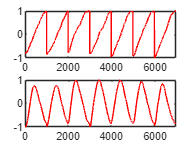

load('DataSet/LASA Data Set/Angle','demos','dt');
for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
end

[xsn,xsnu,tn,input_ps,output_ps,coeff,mu]=Ini.initializingdata(TrajData);
Ini=updateInitial(Ini,coeff,mu,input_ps,output_ps);
figure
for i = 1:size(xsn,1)
    subplot(size(xsn,1),1,i)
    plot(1:size(xsn,2),xsn(i,:),'r')
    hold on
end

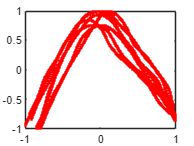


if size(xsn,1)==2
figure
plot(xsn(1,:),xsn(2,:),'.r')
end

## Neural Hybrid System Learning

NHS1=NHS(xsn,tn,Ini);

Starting Maximum Entropy Partitioning with epsilon=80
Number of Partitions 1
Elapsed time is 0.025977 seconds.
Number of Partitions 2
Elapsed time is 0.019214 seconds.
Number of Partitions 3
Elapsed time is 0.011917 seconds.
Number of Partitions 4
Elapsed time is 0.008501 seconds.
Number of Partitions 4
Elapsed time is 0.011343 seconds.
Number of Partitions 4
Elapsed time is 0.010868 seconds.
Number of Partitions 5
Elapsed time is 0.009182 seconds.
Number of Partitions 6
Elapsed time is 0.009117 seconds.
Number of Partitions 7
Elapsed time is 0.008441 seconds.
Number of Partitions 7
Elapsed time is 0.000264 seconds.
Number of Partitions 7
Elapsed time is 0.013583 seconds.
Number of Partitions 8
Elapsed time is 0.011303 seconds.
Number of Partitions 9
Elapsed time is 0.009676 seconds.
Number of Partitions 10
Elapsed time is 0.008221 seconds.
Number of Partitions 10
Elapsed time is 0.000013 seconds.
Number of Partitions 10
Elapsed time is 0.011304 seconds.
Number of Partitions 11
Elapsed

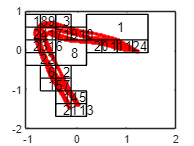

SamplesnPartitionsPlot(NHS1,xsn)

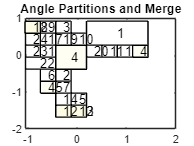

PoltDataPartition(NHS1)

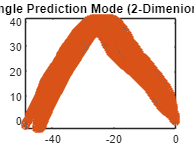

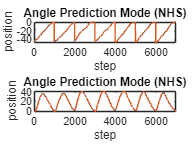

PredictionPlot(NHS1,xsn,tn)

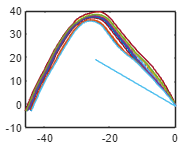

[RandomInput,SimulationTraj]=Runsimulation(NHS1); 

clear xsn tn Ini AbstractionDuration AbstractionEntropy AbstractionNum AbstractionTol coeff idx e i output_ps input_ps

## Transition System Abstration

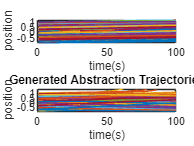

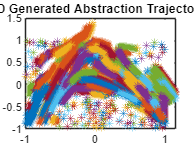

Starting Maximum Entropy Partitioning with epsilon=120
Number of Partitions 1
Elapsed time is 0.056438 seconds.
Number of Partitions 2
Elapsed time is 0.052537 seconds.
Number of Partitions 3
Elapsed time is 0.037673 seconds.
Number of Partitions 4
Elapsed time is 0.026607 seconds.
Number of Partitions 5
Elapsed time is 0.000015 seconds.
Number of Partitions 5
Elapsed time is 0.029972 seconds.
Number of Partitions 6
Elapsed time is 0.026319 seconds.
Number of Partitions 6
Elapsed time is 0.024155 seconds.
Number of Partitions 6
Elapsed time is 0.000012 seconds.
Number of Partitions 6
Elapsed time is 0.038483 seconds.
Number of Partitions 7
Elapsed time is 0.027289 seconds.
Number of Partitions 8
Elapsed time is 0.000033 seconds.
Number of Partitions 8
Elapsed time is 0.034148 seconds.
Number of Partitions 9
Elapsed time is 0.000016 seconds.
Number of Partitions 9
Elapsed time is 0.000005 seconds.
Number of Partitions 9
Elapsed time is 0.034428 seconds.
Number of Partitions 10
Elapsed t

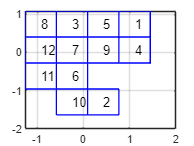

% Abstraction Adjustment
NHS1.Initialize.abstractionnum=400;
NHS1.Initialize.abstractionduration=100;
NHS1.Initialize.abstractiontol=0.7;
NHS1.Initialize.abstractionentropy=120;

NTS1=NTS(NHS1);

fprintf(['The number of the abstraction cell is ',num2str(size(NTS1.P.intervals,2)),'\n'])

The number of the abstraction cell is 12


Elapsed time is 0.415303 seconds.
Elapsed time is 0.543802 seconds.
Elapsed time is 1.313894 seconds.
Elapsed time is 1.037115 seconds.
Elapsed time is 0.509446 seconds.
Elapsed time is 1.520245 seconds.
Elapsed time is 1.543029 seconds.
Elapsed time is 1.035763 seconds.
Elapsed time is 1.260109 seconds.
Elapsed time is 1.517203 seconds.
Elapsed time is 0.743221 seconds.
Elapsed time is 1.249342 seconds.
Elapsed time is 0.119249 seconds.
Elapsed time is 0.219880 seconds.
Elapsed time is 0.540658 seconds.
Elapsed time is 0.464093 seconds.
Elapsed time is 0.232510 seconds.
Elapsed time is 0.662628 seconds.
Elapsed time is 0.662168 seconds.
Elapsed time is 0.434765 seconds.
Elapsed time is 0.541528 seconds.
Elapsed time is 0.656474 seconds.
Elapsed time is 0.327640 seconds.
Elapsed time is 0.552171 seconds.
Elapsed time is 0.157822 seconds.
Elapsed time is 0.322007 seconds.
Elapsed time is 0.787063 seconds.
Elapsed time is 0.633035 seconds.
Elapsed time is 0.313287 seconds.
Elapsed time i

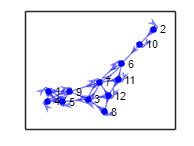

NTS1=TransitionCompute(NTS1);

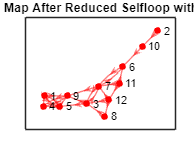

NTS1=ReduceSelfloop(NTS1);

NTS1=CTLFormulaeInput(NTS1);


CTL Syntax:
Cells should be given in form of P1.id(x-1), eg.
   A[]: Always, A[] P1.id1, always in cell 2, when given initial condition
   E<>: Eventually, E<> (P1.id3 or P1.id6) denotes there should exist at least one path, such that there is one time step in cell 4 or cell 7
   A<>: For all paths, Eventually 
   E[]: Exists, Always, E[] P1.id1 means at leat exist one trace such that its always in cell 2
   leadsto: leads to A[] (P1.id0 leadsto P1.id3) denotes for all trace cell 1 leadsto cell 4 always true.




GenerateSystem(NTS1);
